# Modelo de VPH VS IL4

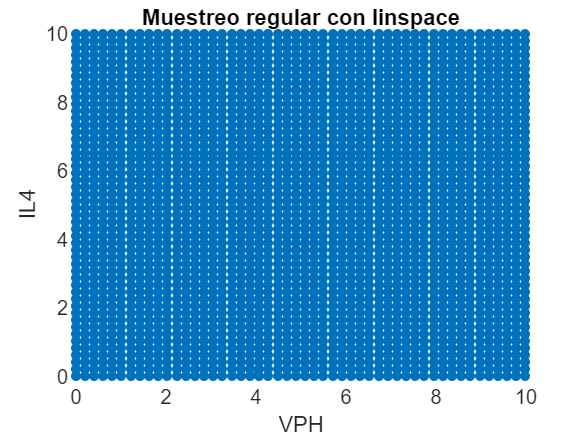

% Preparación del entorno
clear;
clc;
close all;

% Definición simbólica del sistema
syms p53 Stat3 Np63 VPH1 VPH2 IL4

% Parámetros fijos
Pp53 = 1.1380;
N = 0.6184;
k = 1.8558;
B = 1.6019;
ANp63p53 = 1.3864;
C1 = 0.8905;
dNp63p53 = 1.0944;
Dp53 = 0.1597;
Pstat3 = 0.9819;
ANp63s = 0.0053;
Ap53s = 1.1090;
Dstat3 = 0.8895;
PNp63 = 5.7201;
Astat3Np = 0.9350;
C2 = 1.2659;
dp53NP = 0.0000;
C3 = 2.8150;
dNp63Np63 = 0.2113;
DNp63 = 3.3663;

% Ecuaciones del sistema
f1 = (Pp53 + B*(p53^N)/(k^N + p53^N) + ANp63p53*Np63) * C1/(1 + dNp63p53*Np63) * 1/(1+VPH1) - Dp53*(1+VPH2)*p53;
f2 = (Pstat3 + ANp63s*Np63 + Ap53s*p53)*(1+IL4) - Dstat3*Stat3;
f3 = (PNp63 + Astat3Np*Stat3) * C2/(1 + dp53NP*p53) * C3/(1 + dNp63Np63*Np63) - DNp63*Np63;

vars = [p53, Stat3, Np63];

% Grilla de parámetros
nPerAxis = 50; % para tener 20x20 = 400 muestras
VPH_vals = linspace(0, 10, nPerAxis);
IL4_vals = linspace(0, 10, nPerAxis);
[VPH_grid, IL4_grid] = meshgrid(VPH_vals, IL4_vals);

VPH_list = VPH_grid(:);
IL4_list = IL4_grid(:);
nSamples = numel(VPH_list);

% Visualización
VPH_gra = VPH_grid(:);
IL4_gra = IL4_grid(:);
figure;
scatter(VPH_gra, IL4_gra, 25, 'filled');
xlabel('VPH');
ylabel('IL4');
title('Muestreo regular con linspace');
grid on;


% Inicializar almacenamiento de resultados
resultados = [];  % columnas: [VPH, IL4, p53, Stat3, Np63]

% Semillas para vpasolve
seeds = [0.1 0.1 0.1; 1 1 1; 5 5 5; 10 10 10; 20 20 20; 30 30 30; 40 40 40; 50 50 50];

## Paso 1: Resolver el sistema

for i = 1:nSamples
    val_VPH = VPH_list(i);
    val_IL4 = IL4_list(i);

    eqs = [subs(f1, [VPH1, VPH2, IL4], [val_VPH, val_VPH, val_IL4]) == 0, ...
           subs(f2, [VPH1, VPH2, IL4], [val_VPH, val_VPH, val_IL4]) == 0, ...
           subs(f3, [VPH1, VPH2, IL4], [val_VPH, val_VPH, val_IL4]) == 0];

    sols_unicos = [];

    for s = 1:size(seeds, 1)
        seed = seeds(s, :);
        try
            sol = vpasolve(eqs, vars, seed);
            x1 = double(sol.p53);
            x2 = double(sol.Stat3);
            x3 = double(sol.Np63);

            if all(isreal([x1 x2 x3])) && all([x1 x2 x3] >= 0)
                nueva_sol = [x1 x2 x3];
                if isempty(sols_unicos) || all(vecnorm(sols_unicos - nueva_sol, 2, 2) > 1e-3)
                    sols_unicos = [sols_unicos; nueva_sol];
                end
            end
        catch
            continue
        end
    end

    for j = 1:size(sols_unicos, 1)
        resultados = [resultados; val_VPH, val_IL4, sols_unicos(j, :)];
    end
end

% Convertir a tabla para referencia
resultados_tbl = array2table(resultados, ...
    'VariableNames', {'VPH', 'IL4', 'p53', 'Stat3', 'Np63'});


## Paso 2: Crear matrices para surf

p53_grid = NaN(nPerAxis, nPerAxis);
Stat3_grid = NaN(nPerAxis, nPerAxis);
Np63_grid = NaN(nPerAxis, nPerAxis);

for i = 1:nPerAxis
    for j = 1:nPerAxis
        val_VPH = VPH_vals(j);
        val_IL4= IL4_vals(i);

        idx = find(abs(resultados(:,1) - val_VPH) < 1e-3 & abs(resultados(:,2) - val_IL4) < 1e-3);
        if ~isempty(idx)
            % Tomar la primera solución
            p53_grid(i,j) = resultados(idx(1),3);
            Stat3_grid(i,j) = resultados(idx(1),4);
            Np63_grid(i,j) = resultados(idx(1),5);
        end
    end
end


## Paso 3: Graficar superficies

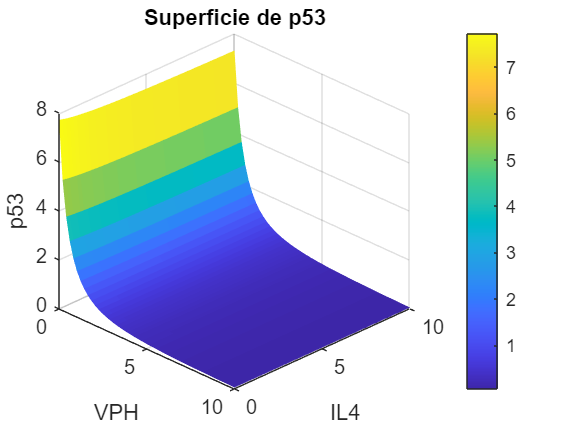

% p53
figure;
surf(VPH_grid, IL4_grid, p53_grid, 'EdgeColor', 'none');
xlabel('VPH'); ylabel('IL4'); zlabel('p53');
title('Superficie de p53');
colorbar; view(45,30);

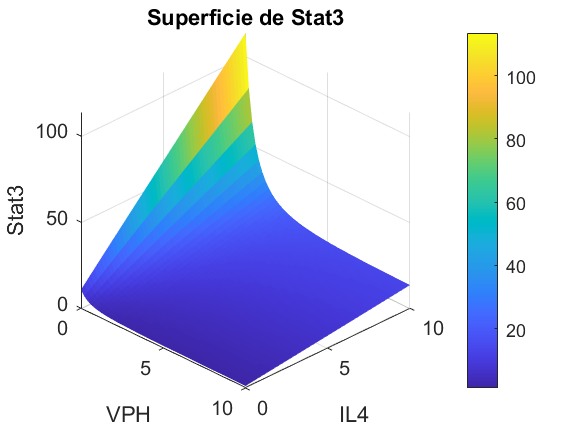


% Stat3
figure;
surf(VPH_grid, IL4_grid, Stat3_grid, 'EdgeColor', 'none');
xlabel('VPH'); ylabel('IL4'); zlabel('Stat3');
title('Superficie de Stat3');
colorbar; view(45,30);

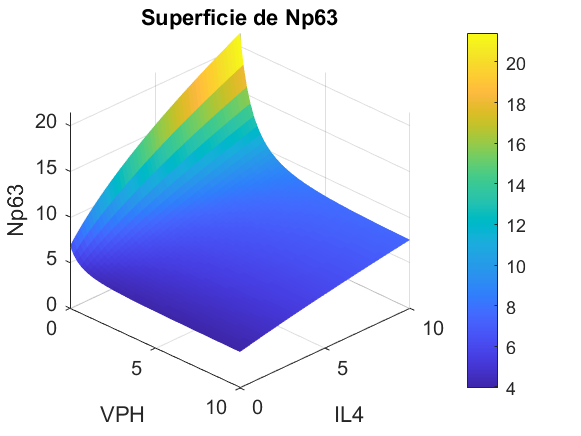


% Np63
figure;
surf(VPH_grid, IL4_grid, Np63_grid, 'EdgeColor', 'none');
xlabel('VPH'); ylabel('IL4'); zlabel('Np63');
title('Superficie de Np63');
colorbar; view(45,30);